# Simscape multibody model og Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Initial test parameters

x_test = 1;
x_size = 1;
v_size = 1;

## Sample controller values (initialisation)

K_vu = 15;     % Kp
t_i_vu = 0.05;   % Tau_i
Kffvu = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)

% Balance controller post integrator
K_post = 1;
t_i_post = 1;

% Balance controller
t_lead_tv = 0;
t_i_tv = 1;
K_tv = 1;

% Balance controller pre filter
t_pre_tv = 0;
t_i_vreft = 1;

% Velocity balance controller
num_lead_vreft = 0;
den_lead_vreft = 1;
K_vreft = 1;

% Position balance controller
K_xvref = 1;
num_lead_xvref = 0;
den_lead_xvref = 1;

s = tf('s');

## Transfer function from previous exercise

Gvu = tf([1.1775 1.68],[1 7.334 7.141])

Gvu =
 
     1.177 s + 1.68
  ---------------------
  s^2 + 7.334 s + 7.141
 
Continuous-time transfer function.
Model Properties


pole(Gvu)

ans =    -6.1782
   -1.1558


zero(Gvu)

ans = -1.4268

## Bodeplot

pole(Gvu)

ans =    -6.1782
   -1.1558


isstable(Gvu)

ans = logical
   1


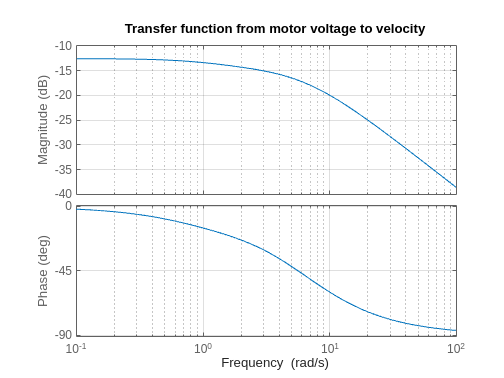

h = figure(100);
bode(Gvu)
grid on
title('Transfer function from motor voltage to velocity')

## Velocity controller

%Design parameters
N_i = 3;
t_r = 0.2; % Rise time

omega_c = 2.2/t_r; % Crossover frequency
tau_i = N_i/omega_c % Integrator time constant

tau_i = 0.2727

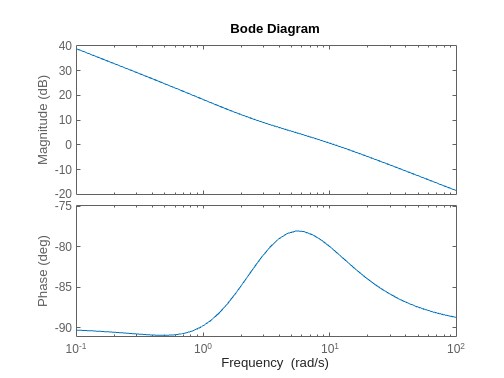

C_i = tf([tau_i 1],[tau_i 0]); %Integrator
Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));

% Open loop
G_vu_ol = Kp*C_i*Gvu;
bode(G_vu_ol)

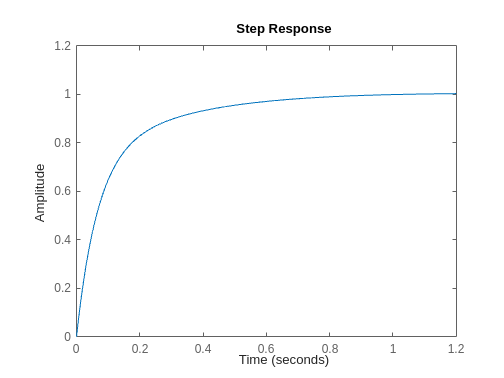

% Closed loop
G_vu_cl = G_vu_ol/(1+G_vu_ol);
step(G_vu_cl)

## Flush values to model

K_vu = Kp

K_vu = 10.1357

t_i_vu = tau_i

t_i_vu = 0.2727

## **Transfer function from velocity to tilt using linearize**

% define points in model
ios(1) = linio(strcat(model,'/vel_cont'),1,'openinput');
ios(2) = linio(strcat(model, '/tilt_angle'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gtv = minreal(tf(num, den))

Gtv =
 
                 -3.982e05 s^4 - 5.145e08 s^3 - 8.856e10 s^2 - 3.181e11 s - 9.517e08
  --------------------------------------------------------------------------------------------------
  s^7 + 2418 s^6 + 1.317e06 s^5 + 1.943e08 s^4 + 9.515e09 s^3 - 4.737e09 s^2 - 7.052e11 s - 1.889e12
 
Continuous-time transfer function.


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


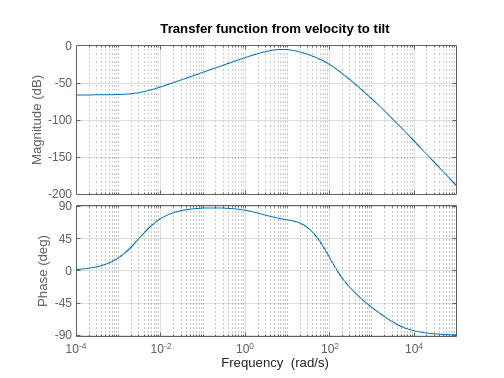

bode(Gtv)
grid on
title('Transfer function from velocity to tilt')

[mag,phase,wout]=bode(Gtv);

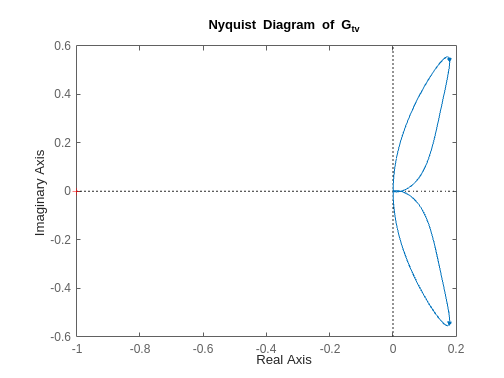

nyquist(Gtv)
title('Nyquist Diagram of G_{tv}')

## Post-Integrator

% Find amplitude peak
[gpeak,fpeak] = getPeakGain(-Gtv)

gpeak = 0.5823

fpeak = 7.5490


% Time constant
tau_i = 1/fpeak

tau_i = 0.1325


% Integrator
C_pi = -(tau_i*s+1)/(tau_i*s)

C_pi =
 
  -0.1325 s - 1
  -------------
    0.1325 s
 
Continuous-time transfer function.
Model Properties



% Open loop
G_post=Gtv*C_pi

G_post =
 
                5.274e04 s^5 + 6.855e07 s^4 + 1.225e10 s^3 + 1.307e11 s^2 + 3.182e11 s + 9.517e08
  -------------------------------------------------------------------------------------------------------------
  0.1325 s^8 + 320.4 s^7 + 1.744e05 s^6 + 2.574e07 s^5 + 1.26e09 s^4 - 6.275e08 s^3 - 9.342e10 s^2 - 2.502e11 s
 
Continuous-time transfer function.


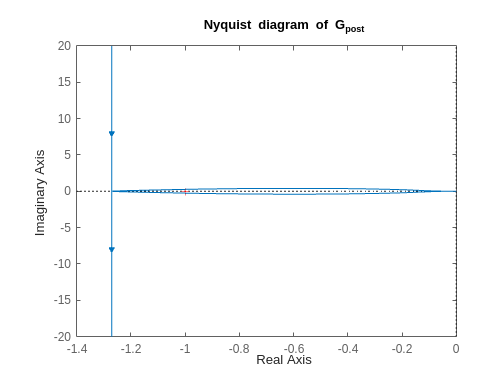

nyquist(G_post)
title('Nyquist diagram of G_{post}')


%Closed loop
G_post_cl=minreal(G_post/(1+G_post))

G_post_cl =
 
                 3.982e05 s^5 + 5.175e08 s^4 + 9.244e10 s^3 + 9.866e11 s^2 + 2.402e12 s + 7.185e09
  ---------------------------------------------------------------------------------------------------------------
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.947e08 s^5 + 1.003e10 s^4 + 8.77e10 s^3 + 2.814e11 s^2 + 5.13e11 s + 7.185e09
 
Continuous-time transfer function.


isstable(G_post_cl)

ans = logical
   1


## Flush values to Simulink

K_post = -1

K_post = -1

t_i_post=tau_i

t_i_post = 0.1325

## Tilt to velocity controller PI-lead (Balance controller)

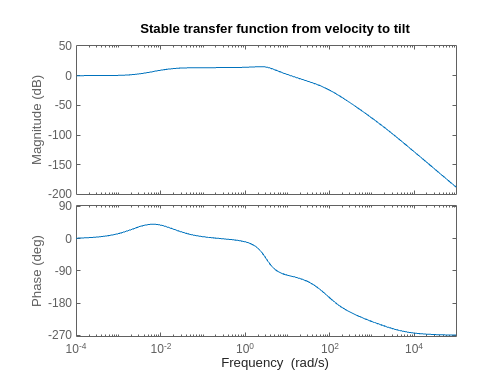

% TF to control
bode(G_post_cl)
title('Stable transfer function from velocity to tilt')


% Design parameters
N_i =4%N_i_tv;

N_i = 4

gamma_m = 70%gamma_tv;

gamma_m = 70

alpha = 0.01%alpha_tv;

alpha = 0.0100


% Phase contributions
phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

% Phase balance equation
phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_post_cl);

%Cross over frequencies
omega_c = interp1(squeeze(phase),wout,phi_G);

% Controller time constants
tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

% Controllers
C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.03235 s + 1
  -------------
    0.03235 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
   0.08088 s + 1
  ---------------
  0.0008088 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_post_cl),omega_c);
Kp = 1/mag;

% New open and closed loop transfer functions
G_tv_ol = minreal(Kp*C_i*C_D*G_post_cl)

G_tv_ol =
 
             9.866e07 s^7 + 1.325e11 s^6 + 2.849e13 s^5 + 1.285e15 s^4 + 1.993e16 s^3 + 1.192e17 s^2 + 2.276e17 s + 6.805e14
  -------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 3655 s^9 + 4.307e06 s^8 + 1.823e09 s^7 + 2.508e11 s^6 + 1.249e13 s^5 + 1.087e14 s^4 + 3.484e14 s^3 + 6.343e14 s^2 + 8.884e12 s
 
Continuous-time transfer function.


G_tv_cl = minreal(G_tv_ol/(1+G_tv_ol))

G_tv_cl =
 
                  9.866e07 s^7 + 1.325e11 s^6 + 2.849e13 s^5 + 1.285e15 s^4 + 1.993e16 s^3 + 1.192e17 s^2 + 2.276e17 s + 6.805e14
  ------------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 3655 s^9 + 4.307e06 s^8 + 1.921e09 s^7 + 3.833e11 s^6 + 4.099e13 s^5 + 1.394e15 s^4 + 2.028e16 s^3 + 1.198e17 s^2 + 2.276e17 s + 6.805e14
 
Continuous-time transfer function.


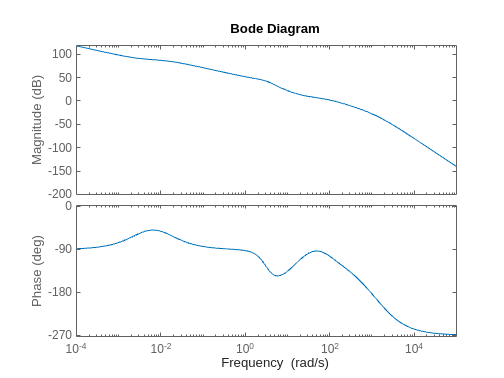


bode(G_tv_ol)

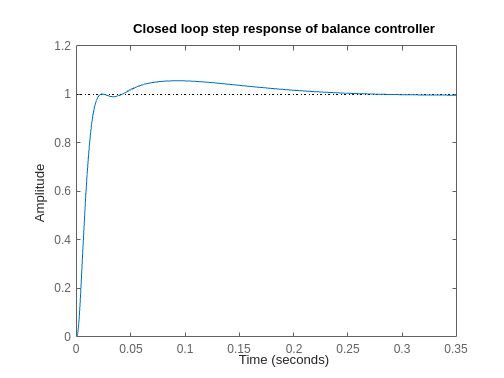

step(G_tv_cl)
title('Closed loop step response of balance controller')

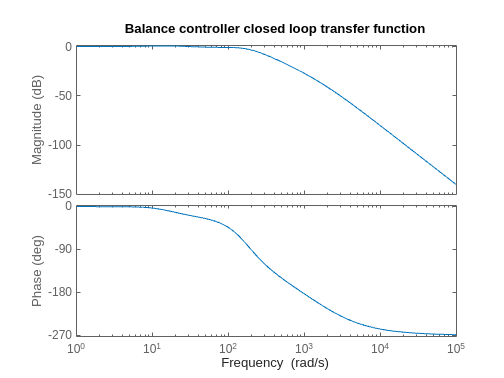

bode(G_tv_cl)
title('Balance controller closed loop transfer function')

## Pre filter

% Find frequency peaks in Balance controller
[mag,phase,wout] = bode(G_tv_cl);
[gpeak,fpeak] = findpeaks(squeeze(mag));

% Filter time constant as 1/omega_peak
tau_pre = 1/wout(fpeak(end))

tau_pre = 0.0633


% Pre filter
G_pre = 1/(s*tau_pre+1)

G_pre =
 
        1
  -------------
  0.06329 s + 1
 
Continuous-time transfer function.
Model Properties



% New transfer function
G_tv_pre = G_tv_cl*G_pre

G_tv_pre =
 
                               9.866e07 s^7 + 1.325e11 s^6 + 2.849e13 s^5 + 1.285e15 s^4 + 1.993e16 s^3 + 1.192e17 s^2 + 2.276e17 s + 6.805e14
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  0.06329 s^11 + 232.3 s^10 + 2.762e05 s^9 + 1.259e08 s^8 + 2.618e10 s^7 + 2.977e12 s^6 + 1.292e14 s^5 + 2.677e15 s^4 + 2.786e16 s^3 + 1.342e17 s^2 + 2.276e17 s + 6.805e14
 
Continuous-time transfer function.


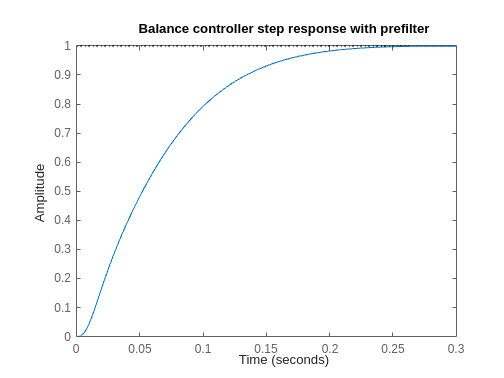

step(G_tv_pre)
title('Balance controller step response with prefilter')

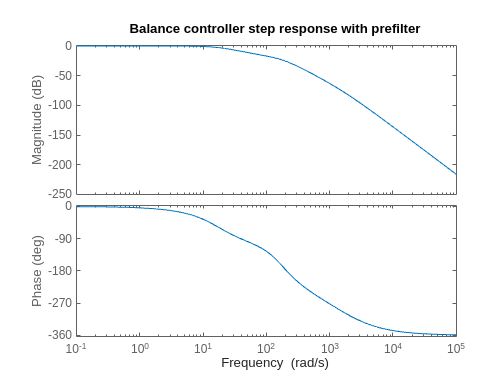

bode(G_tv_pre)
title('Balance controller step response with prefilter')

wout(fpeak(end)) % omega_peak

ans = 15.8006

## Flush values to simulink

t_i_post

t_i_post = 0.1325

t_lead_tv = tau_D

t_lead_tv = 0.0809

t_i_tv = tau_i

t_i_tv = 0.0324

K_tv = Kp

K_tv = 2.4780

t_pre_tv = tau_pre

t_pre_tv = 0.0633

## Transfer function from tilt to velocity using linearize

% define points in model
ios(1) = linio(strcat(model,'/tilt_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_vreft = minreal(tf(num, den))

G_vreft =
 
                         -2.787e08 s^6 - 2.905e11 s^5 - 1.183e13 s^4 - 8.356e13 s^3 + 6.189e14 s^2 + 7.569e15 s + 1.726e16
  -----------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2434 s^9 + 1.435e06 s^8 + 3.164e08 s^7 + 3.007e10 s^6 + 1.41e12 s^5 + 3.187e13 s^4 + 3.481e14 s^3 + 1.707e15 s^2 + 2.909e15 s + 8.696e12
 
Continuous-time transfer function.


## Reference velocity to tilt controller (Velocity balance)

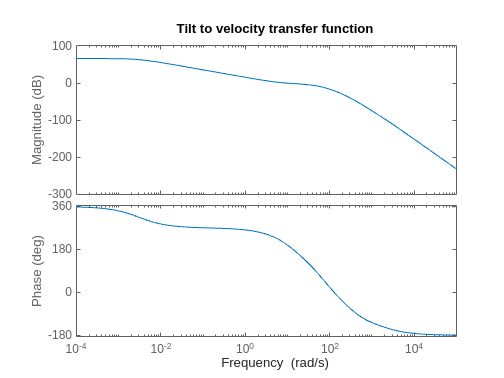

% TF to control
bode(G_vreft)
title('Tilt to velocity transfer function')



% Design parameters
N_i = 5;
gamma_m = 70+360; %+360 as matlab starts bodeplot in +360
alpha = 0.7;

% Phase contributions
phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

% Phase balance equation
phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_vreft);

% Crossover frequency
omega_c = interp1(squeeze(phase),wout,phi_G);

% Controller time constants
tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

% Controllers
C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  2.214 s + 1
  -----------
    2.214 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.5292 s + 1
  ------------
  0.3704 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_vreft),omega_c);
Kp = 1/mag;

% New open and closed loop transfer functions
G_vreft_ol = minreal(Kp*C_i*C_D*G_vreft)

G_vreft_ol =
 
                     -1.195e08 s^8 - 1.248e11 s^7 - 5.361e12 s^6 - 4.779e13 s^5 + 1.771e14 s^4 + 3.835e15 s^3 + 1.522e16 s^2 + 2.009e16 s + 6.315e15
  ---------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 2437 s^11 + 1.441e06 s^10 + 3.203e08 s^9 + 3.092e10 s^8 + 1.491e12 s^7 + 3.568e13 s^6 + 4.341e14 s^5 + 2.647e15 s^4 + 7.518e15 s^3 + 7.861e15 s^2 + 2.347e13 s
 
Continuous-time transfer function.


G_vreft_cl = minreal(G_vreft_ol/(1+G_vreft_ol))

G_vreft_cl =
 
                          -1.195e08 s^8 - 1.248e11 s^7 - 5.361e12 s^6 - 4.779e13 s^5 + 1.771e14 s^4 + 3.835e15 s^3 + 1.522e16 s^2 + 2.009e16 s + 6.315e15
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 2437 s^11 + 1.441e06 s^10 + 3.203e08 s^9 + 3.08e10 s^8 + 1.367e12 s^7 + 3.032e13 s^6 + 3.864e14 s^5 + 2.824e15 s^4 + 1.135e16 s^3 + 2.308e16 s^2 + 2.012e16 s + 6.315e15
 
Continuous-time transfer function.


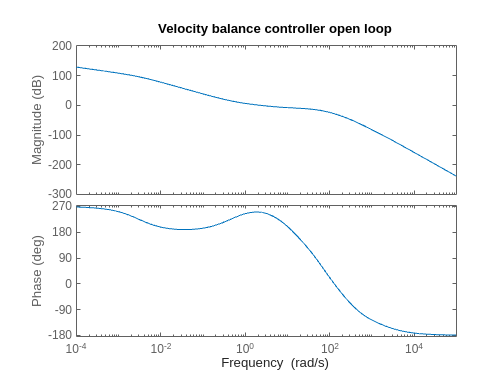


bode(G_vreft_ol)
title('Velocity balance controller open loop')

step(G_vreft_cl)
stepinfo(G_vreft_cl)

ans = struct with fields:
         RiseTime: 0.5252
    TransientTime: 5.7949
     SettlingTime: 6.0998
      SettlingMin: 0.9005
      SettlingMax: 1.1185
        Overshoot: 11.8522
       Undershoot: 21.9141
             Peak: 1.1185
         PeakTime: 2.2254


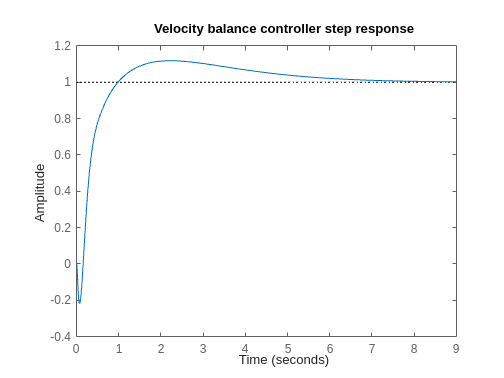

title('Velocity balance controller step response')

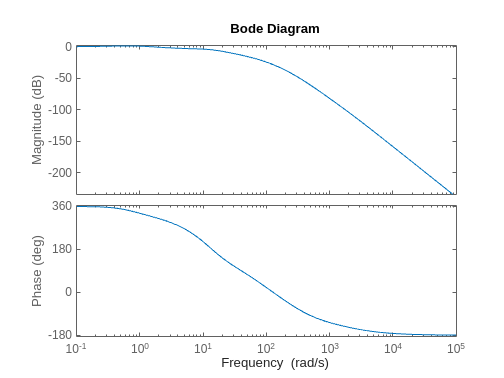

bode(G_vreft_cl)

## Flush values to simulink

t_i_vreft = tau_i

t_i_vreft = 2.2138

[num_lead_vreft,den_lead_vreft] = tfdata(C_D,'v')

num_lead_vreft =     0.5292    1.0000


den_lead_vreft =     0.3704    1.0000


K_vreft = Kp

K_vreft = 0.3001

## Transfer function from velocity to position

% define points in model
ios(1) = linio(strcat(model,'/vel_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/x_pos'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_xvref = minreal(tf(num, den))

G_xvref =
 
                     -4.182e05 s^9 - 5.215e08 s^8 - 1.075e11 s^7 - 4.192e12 s^6 - 4.282e13 s^5 + 5.647e13 s^4 + 3.121e15 s^3 + 1.764e16 s^2 + 3.917e16 s + 3.095e16
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^13 + 2437 s^12 + 1.441e06 s^11 + 3.274e08 s^10 + 3.808e10 s^9 + 1.525e12 s^8 + 3.036e13 s^7 + 3.666e14 s^6 + 2.687e15 s^5 + 1.162e16 s^4 + 2.968e16 s^3 + 4.396e16 s^2 + 3.095e16 s
 
Continuous-time transfer function.


## Velocity to position P-lead controller (Position balance)

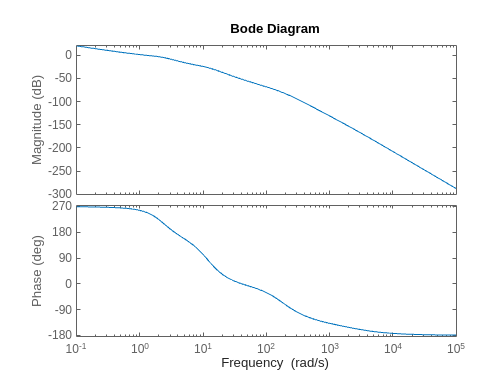

% TF to control
bode(G_xvref)


% Design parameters
gamma_m = 70+360;
alpha = 0.9;

%Phase contribution
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

% Phase balance equation
phi_G = gamma_m - phi_m - 180;
[mag,phase,wout] = bode(G_xvref);

% Crossover frequency
omega_c = interp1(squeeze(phase),wout,phi_G);

% Lead time constant
tau_D = 1/(omega_c*sqrt(alpha));

% Controllers
C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.7768 s + 1
  ------------
  0.6991 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_D*G_xvref),omega_c);
Kp = 1/mag;

% New open and closed loop transfer functions
G_xvref_ol = minreal(Kp*C_D*G_xvref)

G_xvref_ol =
 
                      -4.701e05 s^10 - 5.868e08 s^9 - 1.215e11 s^8 - 4.868e12 s^7 - 5.42e13 s^6 + 1.507e12 s^5 + 3.59e15 s^4 + 2.435e16 s^3 + 6.957e16 s^2 + 9.148e16 s + 4.479e16
  ----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^14 + 2438 s^13 + 1.445e06 s^12 + 3.295e08 s^11 + 3.855e10 s^10 + 1.579e12 s^9 + 3.254e13 s^8 + 4.101e14 s^7 + 3.212e15 s^6 + 1.546e16 s^5 + 4.63e16 s^4 + 8.641e16 s^3 + 9.382e16 s^2 + 4.427e16 s
 
Continuous-time transfer function.


G_xvref_cl = minreal(G_xvref_ol/(1+G_xvref_ol))

G_xvref_cl =
 
                           -4.701e05 s^12 - 1.384e09 s^11 - 1.119e12 s^10 - 2.144e14 s^9 - 9.027e15 s^8 - 1.207e17 s^7 - 3.152e17 s^6 + 6.119e18 s^5 + 6.263e19 s^4 + 2.624e20 s^3 + 5.675e20 s^2 + 6.182e20 s + 2.655e20
  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^16 + 4133 s^15 + 5.584e06 s^14 + 2.793e09 s^13 + 6.056e11 s^12 + 6.887e13 s^11 + 2.936e15 s^10 + 6.471e16 s^9 + 8.822e17 s^8 + 7.769e18 s^7 + 4.498e19 s^6 + 1.764e20 s^5 + 4.837e20 s^4 + 9.337e20 s^3 + 1.199e21 s^2 + 8.807e20 s + 2.655e20
 
Continuous-time transfer function.


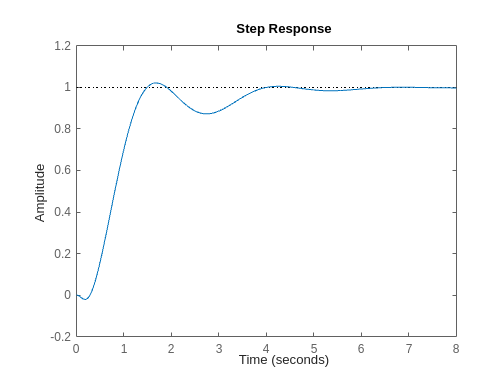


step(G_xvref_cl)

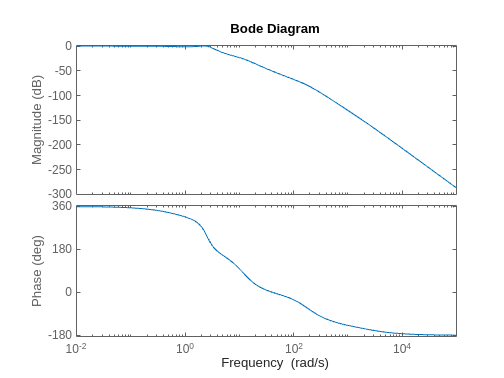

bode(G_xvref_cl)

## Flush values to Simulink

[num_lead_xvref,den_lead_xvref] = tfdata(C_D,'v')

num_lead_xvref =     0.7768    1.0000


den_lead_xvref =     0.6991    1.0000


K_xvref = Kp

K_xvref = 1.0117

## X step test

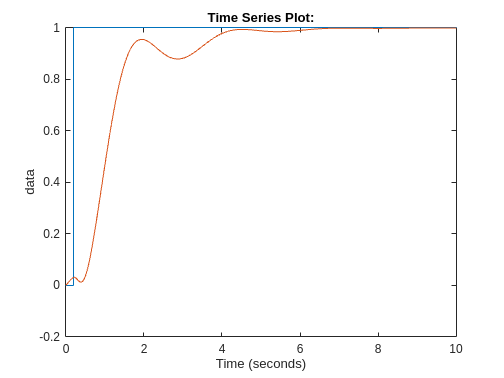

x_test = 1;
x_size = 1;

regsim = sim(model,10);

% Position step
figure(1);
plot(regsim.ref);
hold on;
plot(regsim.x_pos);
hold off;

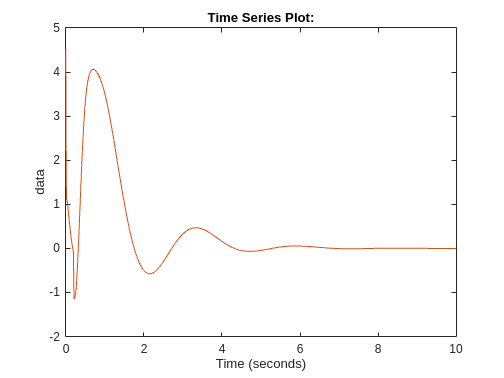


% Motor voltage test
% Should not exceed 9V
figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## v step size

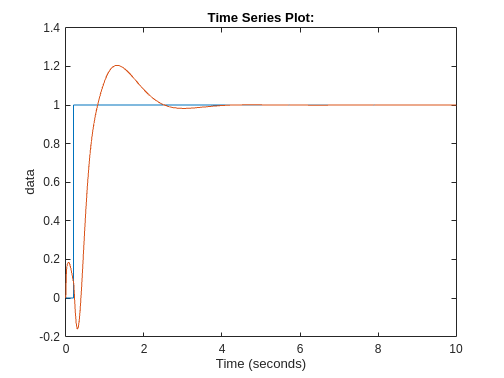

x_test = 0;
v_size = 1;

regsim = sim(model,10);

% Velocity step
figure(1);
plot(regsim.vref);
hold on;
plot(regsim.vel);
hold off;

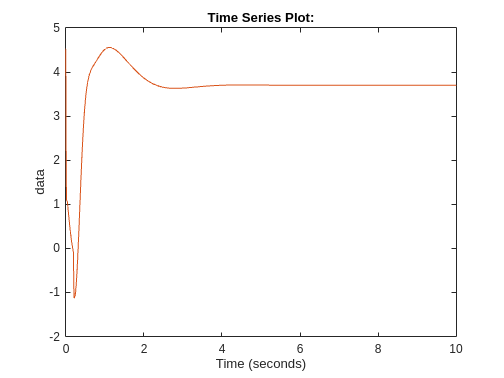


% Motor voltage test
% Should not exceed 9V
figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## Print controller values

K_vu

K_vu = 10.1357

t_i_vu

t_i_vu = 0.2727

K_post

K_post = -1

t_i_post

t_i_post = 0.1325

t_lead_tv

t_lead_tv = 0.0809

t_i_tv

t_i_tv = 0.0324

K_tv

K_tv = 2.4780

t_i_vreft

t_i_vreft = 2.2138

num_lead_vreft

num_lead_vreft =     0.5292    1.0000


den_lead_vreft

den_lead_vreft =     0.3704    1.0000


K_vreft

K_vreft = 0.3001

K_xvref

K_xvref = 1.0117

num_lead_xvref

num_lead_xvref =     0.7768    1.0000


den_lead_xvref

den_lead_xvref =     0.6991    1.0000
